# Evaluación

Ana Itzel Hernández García A01737526

Obtener la **cinemática directa** del  robot:

- **Obtener **el vector de velocidades lineales y el vector de velocidades angulares para los siguientes robots manipuladores

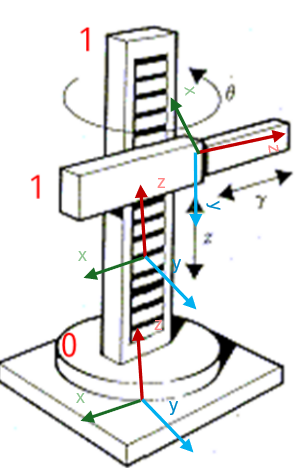

Limpieza de pantalla 

clear all
close all
clc

Declaración de variables simbolicas (**3 grados de libertad**)

Donde hay una rotacional y 2 prismaticas 

syms th(t) l1(t) l2(t) l3(t) t

% configuración del robot, 0 para la rotacional y 1 para las juntas prismáticas
RP = [0 1 1];

% Creación del vector de coordenadas articulares
Q = [th l2 l3];

% Creación del vector de velocidades generalizadas
Qp = diff(Q, t);

% Número de grados de libertad
GDL = size(RP, 2);
GDL_str = num2str(GDL);

## Articulación 1

Posición de la articulación 1 respecto a 0

Debido a que cuenta con una traslación en el eje z se toma en cuenta la longitud que se encuentra en ese eje, es decir l1

P(:,:,1) = [
            0;
            0;
            l1
           ];


Matriz de rotación de la junta 1 respecto a la 0

A la matriz de rotación Z se mantiene debido a que no hay ninguna rotación en sus ejes

R(:,:,1) = [
             cos(th)   -sin(th)     0;
             sin(th)    cos(th)     0;
             0           0            1
             ];

## Articulacion 2

Posición de la articulación 2 respecto a 1

Debido a que cuenta con una traslación en el eje z se toma en cuenta la longitud que se encuentra en ese eje, es decir l2

P(:,:,2) = [
            0;
            0;
            l2
           ];

Matriz de rotación de la junta 2 respecto a 1

Para esta matriz se realiza una doble rotación:  en Y(+90)

R(:,:,2) = rotY(90); 
R(:,:,2)

$$ans = \left(\begin{array}{ccc} 0 & 0 & 1\\ 0 & 1 & 0\\ -1 & 0 & 0 \end{array}\right)$$

## Articulacion 3

Posición de la articulación 3 respecto a la 2

Debido a que cuenta con una traslación en el eje z se toma en cuenta la longitud que se encuentra en ese eje, es decir l3

P(:,:,3) = [
            0;
            0;
            l3
           ];


Matriz de rotación de la junta 3 respecto a la 2 (0°)

Como no hay trasnformación se evalua la rotación Z en 0°

R(:,:,3) = rotZ(0); 
R(:,:,3)

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

## Matrices

% Creación de vector de ceros
vector_zeros = zeros(1,3);

% Inicialización de las amtrices de Transformación Homogenea locales
A(:, :, GDL) = simplify([ ...
                        R(:,:,GDL)      P(:,:,GDL); ...
                        vector_zeros    1 ...
                        ]);

% Inicialización de las amtrices de transformación Homogenea globales
T(:,:,GDL) = simplify([ ...
                        R(:,:,GDL)      P(:,:,GDL); ...
                        vector_zeros    1 ...
                        ]);

% Inicialización de los vectores de posición vistos desde el marco de
% referencia inercial
PO(:,:,GDL) = P(:,:,GDL);

% Inicialización de las matrices de rotación vistas desde el marco de
% referencia inercial
RO(:,:,GDL) = R(:,:,GDL);

for i = 1:GDL
    i_str = num2str(i);

    % Locales
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i) = simplify([ ...
                         R(:,:,i)       P(:,:,i); ...
                         vector_zeros   1 ...
                        ]); A(:,:,i)

    % Globales
    try
        T(:,:,i) = T(:,:,i-1)*A(:,:,i);
    catch
        T(:,:,i) = A(:,:,i); % Caso específico cuando i=1 nos marcaría error en try
    end

    disp(strcat('Matruz de Transformación global T', i_str));
    T(:,:,i) = simplify(T(:,:,i)); T(:,:,i)

    % Obtención de la matriz de rotación "RO" y el vector de traslación PO
    % de la matriz de transformación homogenea global T(:,:, GDL)
    RO(:,:,i) = T(1:3,1:3,i);
    PO(:,:,i) = T(1:3,4,i);
end

Matriz de Transformación local A1


$$ans = \left(\begin{array}{cccc} \cos\left(\mathrm{th}\left(t\right)\right) & -\sin\left(\mathrm{th}\left(t\right)\right) & 0 & 0\\ \sin\left(\mathrm{th}\left(t\right)\right) & \cos\left(\mathrm{th}\left(t\right)\right) & 0 & 0\\ 0 & 0 & 1 & l_{1}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matruz de Transformación global T1


$$ans = \left(\begin{array}{cccc} \cos\left(\mathrm{th}\left(t\right)\right) & -\sin\left(\mathrm{th}\left(t\right)\right) & 0 & 0\\ \sin\left(\mathrm{th}\left(t\right)\right) & \cos\left(\mathrm{th}\left(t\right)\right) & 0 & 0\\ 0 & 0 & 1 & l_{1}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación local A2


$$ans = \left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 1 & 0 & 0\\ -1 & 0 & 0 & l_{2}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matruz de Transformación global T2


$$ans = \left(\begin{array}{cccc} 0 & -\sin\left(\mathrm{th}\left(t\right)\right) & \cos\left(\mathrm{th}\left(t\right)\right) & 0\\ 0 & \cos\left(\mathrm{th}\left(t\right)\right) & \sin\left(\mathrm{th}\left(t\right)\right) & 0\\ -1 & 0 & 0 & l_{1}\left(t\right)+l_{2}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación local A3


$$ans = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & l_{3}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matruz de Transformación global T3


$$ans = \left(\begin{array}{cccc} 0 & -\sin\left(\mathrm{th}\left(t\right)\right) & \cos\left(\mathrm{th}\left(t\right)\right) & \cos\left(\mathrm{th}\left(t\right)\right)\,l_{3}\left(t\right)\\ 0 & \cos\left(\mathrm{th}\left(t\right)\right) & \sin\left(\mathrm{th}\left(t\right)\right) & \sin\left(\mathrm{th}\left(t\right)\right)\,l_{3}\left(t\right)\\ -1 & 0 & 0 & l_{1}\left(t\right)+l_{2}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

En las matrices locales podemos observar que efectivamente en la ultima columna se respeta el vector de posción, mientas que en global concentra las pocisiones de las articulaciones.

De igual manera las matrices locales contienen cada matriz de rotación 3x3 de cada rotación mientras la global contiene la general del sistema

### Jacobiano lineal y angular de forma analítica

% Inicialización de jacobianos analíticos
Jv_a(:,GDL) = PO(:,:,GDL); % Lineal 
Jw_a(:,GDL) = PO(:,:,GDL); % Angular

for k = 1:GDL
    if(RP(k) == 0)
        % Para las articulaciones rotacionales
        try
            Jv_a(:,k) = cross(RO(:,3,k-1), PO(:,:,GDL) - PO(:,:,k-1));
            Jw_a(:,k) = RO(:,3,k-1);
        catch
            Jv_a(:,k) = cross([0 0 1], PO(:,:,GDL)); % Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k) = [0 0 1]; % Si no hay matriz de rotación previa se obtiene la matriz identidad
        end
    elseif(RP(k) == 1)
        % Para las articulaciones prismáticas
        try
            Jv_a(:,k) = RO(:,3,k-1);
        catch
            Jv_a(:,k) = [0,0,1]; % Si no hay matriz de rotación previa se obtiene la matriz identidad
        end
            Jw_a(:,k) = [0 0 0];
    end
end


## Despliegue

disp('Jacobiano lineal obtenido de forma analítica'); Jv_a = simplify(Jv_a)

Jacobiano lineal obtenido de forma analítica


$$Jv\_a = \left(\begin{array}{ccc} -\sin\left(\mathrm{th}\left(t\right)\right)\,l_{3}\left(t\right) & 0 & \cos\left(\mathrm{th}\left(t\right)\right)\\ \cos\left(\mathrm{th}\left(t\right)\right)\,l_{3}\left(t\right) & 0 & \sin\left(\mathrm{th}\left(t\right)\right)\\ 0 & 1 & 0 \end{array}\right)$$

disp('Jacobiano angular obtenido de forma ananlítica'); Jw_a = simplify(Jw_a)

Jacobiano angular obtenido de forma ananlítica


$$Jw\_a = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 1 & 0 & 0 \end{array}\right)$$

Aquí, en el vecto de velocidad líneal podemos observar el movimiento de la articulación angular y la prismatica 3 interactuan entres si, mientras que la articulación primatica 2 se mueve en el eje z sin afectar a las otras

disp('Velocidad lineal obtenida mediante el Jacobiano lineal'); V = simplify(Jv_a * Qp')

Velocidad lineal obtenida mediante el Jacobiano lineal


$$V(t) = \left(\begin{array}{c} \bar{\frac{\partial }{\partial t}l_{3}\left(t\right)}\,\cos\left(\mathrm{th}\left(t\right)\right)-\bar{\frac{\partial }{\partial t}\mathrm{th}\left(t\right)}\,\sin\left(\mathrm{th}\left(t\right)\right)\,l_{3}\left(t\right)\\ \bar{\frac{\partial }{\partial t}l_{3}\left(t\right)}\,\sin\left(\mathrm{th}\left(t\right)\right)+\bar{\frac{\partial }{\partial t}\mathrm{th}\left(t\right)}\,\cos\left(\mathrm{th}\left(t\right)\right)\,l_{3}\left(t\right)\\ \bar{\frac{\partial }{\partial t}l_{2}\left(t\right)} \end{array}\right)$$

Como tenemos movimientos líneales, solo contamos con 1 ángulo y por lo tanto solo se mueve la articulación 1

disp('Velocidad angular obtenida mediante el Jacobiano angular'); W = simplify(Jw_a * Qp')

Velocidad angular obtenida mediante el Jacobiano angular


$$W(t) = \left(\begin{array}{c} 0\\ 0\\ \bar{\frac{\partial }{\partial t}\mathrm{th}\left(t\right)} \end{array}\right)$$

## Funciones de rotacion

function r_x = rotX(th)
    r_x = [1 0 0; 0 cosd(th) -sind(th); 0 sind(th) cosd(th)];
end

function r_y = rotY(th)
    r_y = [cosd(th) 0 sind(th); 0 1 0; -sind(th) 0 cosd(th)];
end

function r_z = rotZ(th)
    r_z = [cosd(th) -sind(th) 0; sind(th) cosd(th) 0; 0 0 1];
end